# Shift Signal Generation

This Matlab Live is closely derived from the ModulationClassificationByUsingFPGAExample.mlx. The first half of this Matlab Live serves as a step by step demonstration on how new modulation schemes were introduced and provides visualizations in the form of IQ Constellation and Time Series Plots. 

The second half of this file provides the steps for generating signal traces with specified parameters for all 18 modulation schemes. Not only can users genereate seven new digital modulation schemes, but sampling error offsets can be carefully manipulated to simulated real-world wireless communication impairements.

## Introducing New Modulation Schemes

In the original Modulation Classification with Deep Learning Demo, we are provided with 11 modulation schemes (8 digital and 3 analog). The digital schemes provided are Binary phase shift keying (BPSK), Quadrature phase shift keying (QPSK), 8-ary phase shift keying (8-PSK), 16-ary quadrature amplitude modulation (16-QAM), 64-ary quadrature amplitude modulation (64-QAM), 4-ary pulse amplitude modulation (PAM4), Gaussian frequency shift keying (GFSK), and Continuous phase frequency shift keying (CPFSK). The analog schemes implemented are Broadcast FM (B-FM), Double sideband amplitude modulation (DSB-AM), and Single sideband amplitude modulation (SSB-AM).

To expand our set of modulation schemes, we referenced those included in the RadioML 2018 dataset, with a particular focus on the digital modulation types. RadioML contains a total of 24 modulation schemes—19 digital and 5 analog. From this dataset, we incorporated several higher-order Amplitude Phase Shift Keying (APSK) and Quadrature Amplitude Modulation (QAM) schemes that were not initially implemented in the MATLAB demo. Specifically, we added 32-QAM, 128-QAM, 256-QAM, as well as 16-APSK, 32-APSK, 64-APSK, and 128-APSK.

To better highlight the characteristics of each modulation scheme, the following visualizations use a frame size of 4096 IQ samples (512 symbols) instead of the standard 1024 samples. This larger frame size allows for a clearer depiction of each scheme’s distinct features.However, for dataset generation during testing, the frame size will remain at 1024 IQ samples since the trained CNN takes 1024 channel-impaired samples and predicts the modulation type of each frame. 


clear;
rng(123456);
modulationTypes = categorical(["BPSK", "QPSK", "8PSK", ...
  "16QAM", "64QAM", "PAM4", "GFSK", "CPFSK", ...
  "B-FM", "DSB-AM", "SSB-AM"]);

%Please Modify Directory as Needed
%% Directory on Lab Machine
%target_directory = '/home/anaghmishra/Documents/OneDrive_MATLAB/Examples/R2024b/deeplearning_shared/ModulationClassificationByUsingFPGAExample';
%% Directory on Personal Machine
target_directory = 'C:\Users\anagh\OneDrive - University of Cincinnati\FPGA_Research\RadioShift\src';

if ~strcmp(pwd, target_directory)
    cd(target_directory);
end

Error using cd
Unable to change current folder to '/home/anaghmishra/Documents/Repos/RadioShift/C:\Users\anagh\OneDrive - University of Cincinnati\FPGA_Research\RadioShift\src' (Name is nonexistent or not a folder).


% the same frames every time the simulation is run
new_ModTypes = categorical(["32QAM", "128QAM","256QAM", "16APSK", "32APSK", "64APSK", "128APSK"]);
numModulationTypes = length(new_ModTypes);

sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
HighDataQty = 4;
fs = 200e3;             % Sample rate

for modType = 1:numModulationTypes

    dataSrc = dlhdlhelperModClassGetSource(new_ModTypes(modType), sps, (spf*HighDataQty), fs);
    modulator = dlhdlhelperModClassGetModulator(new_ModTypes(modType), sps, fs);
    % Generate random data
    x = dataSrc();  
    % Modulate
    y = modulator(x);  

    figure;
    plot(real(y), imag(y), 'x');
    xlabel('In-phase (I)');
    ylabel('Quadrature (Q)');
    sps_str = string(spf * HighDataQty);
    title_str = string(new_ModTypes(modType)) + " using " + sps_str + " samples."; 

    title(title_str);% Convert categorical to string
    axis equal; grid on;
    % Uncomment the line before to save generated images
    %saveas(gcf, ['IQPlot_', char(new_ModTypes(modType)), '.png']);
    fprintf("Size of Data Source: %i", length(x));
    fprintf("Size of Modulated Signal: %i", length(y));
    power = real(y).^2 + imag(y).^2;
    power_sum = sum(power);
    fprintf("Summed Power of Modulated Signal: %i", power_sum);
    figure;
    spf_plot = size(y,1);
    t = 1000*(0:spf_plot-1)/fs;
    plot(t,real(y), '-'); grid on; axis equal; axis square
    hold on
    plot(t,imag(y), '-'); grid on; axis equal; axis square
    hold off
    title_str = string(new_ModTypes(modType)) + " Amplitude vs Time";
    title(title_str);
    xlabel('Time (ms)'); ylabel('Amplitude');
    legend("Real", "Imaginary");
    % Uncomment the line before to save generated images
    % saveas(gcf, ['TSPlot_', char(new_ModTypes(modType)), '.png']);
end

## Visualization of All Modulated Schemes + Channel Impairment

Having established visualizations for the baseline modulation schemes, it is equally important to analyze how these modulated signals behave after passing through a realistic communication channel—specifically one affected by fading and noise. To simulate this, we introduce a Rician fading channel, which models a dominant line-of-sight (LOS) path along with multiple weaker reflected paths. 

In our setup, the center frequency is set to 902 MHz (fc = 902e6) and the sampling frequency is 200 kHz (fs = 200e3). The signal-to-noise ratio (SNR) is fixed at 30 dB to simulate a clean environment. The SNR is used when imposing additive white gaussian noise to the received data. To model multipath effects, we define three distinct path delays: 0, 1.8, and 3.4 samples, normalized by the sampling rate. These correspond to average path gains of 0, –2, and –10 dB respectively. The Rician channel is further characterized by a K-factor of 4, indicating a relatively strong LOS component, and a maximum Doppler shift of 4 Hz to simulate mobility-induced variations.

This channel is implemented in MATLAB using the comm.RicianChannel System object, where all the aforementioned parameters are configured to accurately emulate real-world wireless fading conditions.

Please note that we iterate through the first three modulation schemes twice to provide visualization examples using a smaller number of samples. As mentioned earlier, we use 4096 samples for visualization purposes; however, the actual data generation will use 1024 samples.

iter = 0;
Complete_ModSchemes = categorical(["BPSK", "QPSK", "8PSK", ...
  "16QAM","32QAM", "64QAM", "128QAM", "256QAM",...
  "16APSK", "32APSK", "64APSK", "128APSK",...
  "PAM4", "GFSK", "CPFSK", ...
  "B-FM", "DSB-AM", "SSB-AM"]);

Complete_ModSchemes_Count = length(Complete_ModSchemes);

fs = 200e3; %NOTE: Sampling Frequency 200MHz
SNR = 30;
sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
sigbymod = containers.Map(); % Create a map to store signals with keys as modulation scheme names

multipathChannel = comm.RicianChannel(... 
    'SampleRate', fs, ... 
    'PathDelays', [0 1.8 3.4] / 200e3, ...
    'AveragePathGains', [0 -2 -10], ...
    'KFactor', 4, ...                     
    'MaximumDopplerShift', 4);

frequencyShifter = comm.PhaseFrequencyOffset('SampleRate', fs);
for ind = 1:2
    
    for modType = 1:Complete_ModSchemes_Count
        if(iter < 3)
            HighDataQty = 1;
            addOnString = " with 1024 Samples";
            iter = iter + 1;
        elseif (iter == 3)
            iter = iter + 1;
            HighDataQty = 4;
            addOnString = " 4096 Samples";
            break;
        end
    
        dataSrc = dlhdlhelperModClassGetSource(Complete_ModSchemes(modType), sps, spf*HighDataQty, fs);
        modulator = dlhdlhelperModClassGetModulator(Complete_ModSchemes(modType), sps, fs);
        % Generate random data
        x = dataSrc();  
        % Modulate
        tx = modulator(x); 
        % Apply an independent multipath channel
        reset(multipathChannel)
    
        outMultipathChan = multipathChannel(tx); %Filterting the inputted signal through the Rician Channel
        y = awgn(outMultipathChan,SNR,0);
        % Assign signal to the map using the modulation scheme name as the key
        sigbymod(char(Complete_ModSchemes(modType))) = y;
    
        figure;
        plot(real(y), imag(y), 'x');
        xlabel('In-phase (I)');
        ylabel('Quadrature (Q)');
        sps_str = string(spf * HighDataQty);
        title_str = string(Complete_ModSchemes(modType)) + " with Channel Fading "+ addOnString; 
        title(title_str);% Convert categorical to string
        axis equal; grid on;
        % Uncomment the line before to save generated images
        %saveas(gcf, strjoin(["Fading_IQPlot_", string(Complete_ModSchemes(modType)), string(spf*HighDataQty), ".png"], ""));
                
        figure;
        spf_len = size(y,1);
        t = 1000*(0:spf_len-1)/fs;
        plot(t,real(y), '-'); grid on; axis equal; axis square
        hold on
        plot(t,imag(y), '-'); grid on; axis equal; axis square
        hold off
        title_str = string(Complete_ModSchemes(modType)) + " Amplitude vs Time";
        title(title_str);
        xlabel('Time (ms)'); ylabel('Amplitude');
        legend("Real", "Imaginary");
        % Uncomment the line below to save generaed images
        %saveas(gcf, strjoin(["Fading_TSPlot_", string(Complete_ModSchemes(modType)), string(spf*HighDataQty), ".png"], ""));
    end 
end

## Comparing APSK vs DVBSAPSK

% Modulate
%Original Scheme for APSK Modulation
configs(1).x = 0:15;
configs(1).constellation = [4, 12];
configs(1).radii = [1, 3];

configs(2).x = 0:31;
configs(2).constellation = [4, 12, 16];
configs(2).radii = [1, 3, 4];

configs(3).x = 0:63;
configs(3).constellation = [4, 12, 16, 32];
configs(3).radii = [1, 3, 4, 8];

configs(4).x = 0:127;
configs(4).constellation = [4, 12, 20, 36, 56];
configs(4).radii = [1, 3, 5, 9, 14];


for i = 1:length(configs)
    % APSK mod
    figure;
    subplot(1,2,1);
    syms = apskmod(configs(i).x, configs(i).constellation, configs(i).radii);
    % Plotting
    plot(real(syms), imag(syms), 'x', 'LineWidth', 1.5);
    axis equal;
    axis padded;
    title_str1 = 'Custom ' + string((configs(i).x(end)+1)) +' APSK';
    title(title_str1);

    % DVB-S2X mod
    M = length(configs(i).x);  % M-ary
    syms_dvb = dvbsapskmod(configs(i).x, M, 's2x');
    
    subplot(1,2,2);
    plot(real(syms_dvb), imag(syms_dvb), 'x', 'LineWidth', 1.5);
    axis equal;
    axis padded;
    title_str2 = string((configs(i).x(end)+1)) +' DVBS-APSK';
    title(title_str2);

end




## **Sampling Rate Offset**

To realistically model receiver-side imperfections, we introduce a simulation of sampling clock drift. This accounts for discrepancies between transmitter and receiver clocks, which are often specified in datasheets as an error in parts per million (ppm). Such mismatches can result in sampling time offsets, potentially affecting demodulation performance.

In our simulation, the expected base clock frequency is set to 1 MHz (exp_clk = 1e3), which is scaled by a factor of 200 to yield a sampling rate of 200 MHz (exp_sr = exp_clk * Clock_Scaling). From this, the nominal sampling period is calculated as the inverse of the sampling rate (exp_per = 1 / exp_sr). To model timing drift, we define a variable err_ppm representing the ppm error between clocks. The sign and direction of this error are controlled by a scaling parameter sq_st

- sq_st = 1 indicates that the receiver clock is running faster than expected (i.e., the clock is "squeezed," and the period shortens).

- sq_st = -1 indicates a slower clock (i.e., the clock is "stretched," and the period lengthens).

% Determine clock offset factor
maxOffset = 5;
fc = 902e6;
clockOffset = (rand() * 2*maxOffset) - maxOffset;
C = 1 + clockOffset / 1e6;
% Mathemtical Representation of Clock Offset
% Add frequency offset
frequencyShifter.FrequencyOffset = -(C-1)*fc; %Scaling Factor * Center Frequency
outFreqShifter = frequencyShifter(outMultipathChan); %Signal coming out of the Multipath Fading Channel

bpsk_txsig = sigbymod("BPSK");
clear [err_ppm, rx_fs, rx_t, tx_fs, tx_t, outTimeDrift];
% Add sampling time drift
exp_clk = 1e3; %1MHz
Clock_Scaling = 200; %200 Khz

%--------Expected Values---------------%
tx_fs = exp_clk*Clock_Scaling;
tx_per = 1/tx_fs;

%--------Control Params---------------%
err_ppm = 10000;
sq_st = -1; %1 = Increasing Frequency = Squeeze ... -1 = Decreasing Frequency Stretching
clock_desc = "";
err_ppm = sq_st*err_ppm;
fs_deviation = (err_ppm*tx_fs)/1e6;
rx_fs = (tx_fs + fs_deviation);
if(sq_st>0)
   clock_desc = "Squeezed";
else
   clock_desc = "Stretched";
end

## Receiver Sampling Error Method 1

There are two ways to simulate the sampling operation on the receiver side. The first approach creates the same number of samples as the transmitted signals, but the time-stamps are divided based on the deviated sampling frequecy. Using the new timeline, the signal values are approximated using interpolation. This approach results in a consistent number of signals per frame (spf), however if the receiver works on the basis of acquire a fixed numbeer of samples, would the receiver sample the first SPS samples and then shut off? Would this mean the receiver would miss out on some of the signal it was supposed to sample if the Rx sampling frequency is much faster? And if the sampling frequency is much slower, would it be possible that the signal it was receiving finished/terminated before it acquired all its samples?

tx_t = (0:length(bpsk_txsig)-1)' / tx_fs;
rx_t = (0:length(bpsk_txsig)-1)' / rx_fs;
outTimeDrift = interp1(real(tx_t), bpsk_txsig, real(rx_t));

%Number of Points to Plot
plots_pts = 20;
figure;
plot(tx_t(1:plots_pts),(real(bpsk_txsig(1:plots_pts))), '-'); grid on; axis equal; axis square
hold on
plot(rx_t(1:plots_pts),(real(outTimeDrift(1:plots_pts))), '-'); grid on; axis equal; axis square 
xlabel('Time (ms)'); ylabel('Amplitude');
title_string = "BPSK Sampling Offset with Deviation of " + fs_deviation + " Hz ("+err_ppm+" PPM)"; 
title(title_string);

legend(["Original Signal", "Sampling Offset Signal"], "Position", [0.5954 0.8297 0.4459, 0.1117])
fprintf("The Receivers Sampling Clock is %s with Clock Drift of %i " + ...
        "PPM between Tx and Rx sampling Clock.", clock_desc, abs(err_ppm));

## Receiver Sampling Error Method 2

The second approach creates frame that spans the same timeframe as the transmitted signal, however the number of samples varies based on the deviated signals period. Hence, if the sampling frequency is higher on the receivers end, the period is shorter, hence a larger number of samples are accumulated at the receivier. This approach follows the idea that the signal will continue to sample the receiving signal until the signal is terminated. Unfortunately, this approach may be problematic when looking at it from the deep learning perspective since the frame will not be of consistent length.

tx_t_2 = (0:length(bpsk_txsig)-1)' / tx_fs;
rx_per = 1/rx_fs;
rx_t_2  = (0:rx_per:tx_t(end))';
outTimeDrift_2 = interp1(real(tx_t_2), bpsk_txsig, real(rx_t_2));


%Number of Points to Plot
plots_pts = 20;
figure;
plot(tx_t_2(1:plots_pts),(real(bpsk_txsig(1:plots_pts))), '-'); grid on; axis equal; axis square
hold on
plot(rx_t_2(1:plots_pts),(real(outTimeDrift_2(1:plots_pts))), '-'); grid on; axis equal; axis square 
xlabel('Time (ms)'); ylabel('Amplitude');
title_string = "BPSK Sampling Offset with Deviation of " + fs_deviation + " Hz ("+err_ppm+" PPM)"; 
title(title_string);

legend(["Original Signal", "Sampling Offset Signal"], "Position", [0.5954 0.8297 0.4459, 0.1117])
fprintf("The Receivers Sampling Clock is %s with Clock Drift of %i " + ...
        "PPM between Tx and Rx sampling Clock.", clock_desc, abs(err_ppm));


## **Waveform Generation for Training**

Generate 10,000 frames for each modulation type, where 80% of the frames are used for training, 10% are used for validation and 10% are used for testing. Use the training and validation frames during the network training phase. You obtain the final classification accuracy by using test frames. Each frame is 1024 samples long and has a sample rate of 200 kHz. For digital modulation types, eight samples represent a symbol. The network makes each decision based on single frames rather than on multiple consecutive frames (as in video). Assume a center frequency of 902 MHz and 100 MHz for the digital and analog modulation types, respectively.

clear
clc
close all
numFramesPerModType = 4096;
sps = 8;                % Samles per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
fs = 200e3;             % Sample rate
fc = [902e6 100e6];     % Center frequencies
snr_levels = (0:2:30);

% modulationTypes = categorical(["BPSK", "QPSK", "8PSK", ...
%   "16QAM","32QAM", "64QAM", "128QAM", "256QAM",...
%   "16APSK", "32APSK", "64APSK", "128APSK",...
%   "GFSK", "CPFSK", "FM", "AM-DSB-SC", "AM-SSB-SC"]);
modulationTypes = categorical(["16APSK", "32APSK", "64APSK", "128APSK",...
  "GFSK", "CPFSK", "FM", "AM-DSB-SC", "AM-SSB-SC"]);

**Create Channel Impairments**

Pass each frame through a channel by using:

- AWGN

- Rician multipath fading

- Clock offset, resulting in center frequency offset and sampling time drift

Because the network in this example makes decisions based on single frames, each frame must pass through an independent channel **AWGN**.

The channel adds AWGN by using an SNR of 30 dB. Implement the channel by using the [`awgn`](docid:comm_ref#fp1221678) (Communications Toolbox) function.

**Rician Multipath**

The channel passes the signals through a Rician multipath fading channel by using the [`comm.RicianChannel`](docid:comm_ref#btzx8bh-1) (Communications Toolbox) System object. Assume a delay profile of [0 1.8 3.4] samples that have corresponding average path gains of [0 -2 -10] dB. The K-factor is 4 and the maximum Doppler shift is 4 Hz, which is equivalent to a walking speed at 902 MHz. Implement the channel by using the following settings.

**Clock Offset**

Clock offset occurs because of the inaccuracies of internal clock sources of transmitters and receivers. Clock offset causes the center frequency, which is used to downconvert the signal to baseband, and the digital-to-analog converter sampling rate to differ from theoretical values. The channel simulator uses the clock offset factor *C*, expressed as *C*=1+Δclock106, where Δclock is the clock offset. For each frame, the channel generates a random Δclock value from a uniformly distributed set of values in the range [−maxΔclock maxΔclock], where maxΔclock is the maximum clock offset. Clock offset is measured in parts per million (ppm).

MAX_PPM = 0;

%If we want to Hard Set a Clock Offset
%% Creating a Parameter to control whether we stretch (decrease) or squeeze (increase) the Rx Sampling Clock frequency
%% Str_Sq_Param = 1:  Increase Clock Frequency (Squeeze)
%% Str_Sq_Param = -1: Decrease Clock Frequency (Stretch)
Str_Sq_Param = 1; 
Set_PPM = (Str_Sq_Param * MAX_PPM)/1e6'

Set_PPM = 0

**Frequency Offset**

Subject each frame to a frequency offset based on clock offset factor *C* and the center frequency. Implement the channel by using the [`comm.PhaseFrequencyOffset`](docid:comm_ref#bsnfizs_4) (Communications Toolbox).

**Sampling Rate Offset**

Each frame is subjected to a sampling rate offset determined by the `MaximumClockOffset` parameter assigned to the receiver clock. This parameter can be hard-set to the value of `Set_PPM` by setting `HardSetOffsetPPM` to 1, in which case the PPM offset will be exactly `Set_PPM`. Alternatively, if `HardSetOffsetPPM` is set to 0, `Set_PPM` will serve as the upper and lower bound for a randomly generated PPM offset value.

**Combined Channel**

To apply all three channel impairments to the frames, use the dlhdlhelperModClassTestChannel object.

channel = dlhdlhelperModClassTestChannel(...
  'SampleRate', fs, ...
  'SNR', snr_levels(1), ...
  'PathDelays', [0 1.8 3.4] / fs, ...
  'AveragePathGains', [0 -2 -10], ...
  'KFactor', 4, ...
  'MaximumDopplerShift', 4, ...
  'MaximumClockOffset', Set_PPM, ... %Set this as max PPM
  'HardSetOffsetPPM', 1,... % If this is set as 1, we hardset the Max PPM, otherwise we use a random PPM
  'CenterFrequency', 902e6)

channel =   dlhdlhelperModClassTestChannel with properties:

                    SNR: 0
        CenterFrequency: 902000000
             SampleRate: 200000
             PathDelays: [0 9.0000e-06 1.7000e-05]
       AveragePathGains: [0 -2 -10]
                KFactor: 4
    MaximumDopplerShift: 4
     MaximumClockOffset: 0
       HardSetOffsetPPM: 1


You can view basic information about the channel by using the info object function.

chInfo = info(channel)

chInfo = struct with fields:
               ChannelDelay: 6
     MaximumFrequencyOffset: 0
    MaximumSampleRateOffset: 0


**Waveform Generation**

Create a loop that generates channel-impaired frames for each modulation type and stores the frames with their corresponding labels in MAT files. By saving the data into files, you do not have to eliminate the need to generate the data every time you run this example. You can also share the data more effectively.

Remove a random number of samples from the beginning of each frame to remove transients and to make sure that the frames have a random starting point with respect to the symbol boundaries.

% Set the random number generator to a known state to be able to regenerate
% the same frames every time the simulation is run
rng(1235)
uint8_scale = 8;
numModulationTypes = length(modulationTypes);

channelInfo = info(channel);
transDelay = 50;
% dataDirectory = fullfile(pwd,"ModClassDataFiles");

dataDirectory = fullfile('home/anaghmishra', 'ModClassDataFiles')

dataDirectory = 'home/anaghmishra/ModClassDataFiles'

dataDirectory_uint8 = fullfile(dataDirectory, "int8");
dataDirectory_float32 = fullfile(dataDirectory, "float32");
disp("Data file directory is " + dataDirectory);

Data file directory is home/anaghmishra/ModClassDataFiles


Generating data and saving in data files...


00:41:14 - Generating 16APSK frames
00:44:52 - Generating 32APSK frames
00:48:31 - Generating 64APSK frames
00:52:10 - Generating 128APSK frames


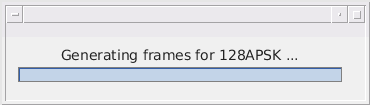

00:55:52 - Generating GFSK frames


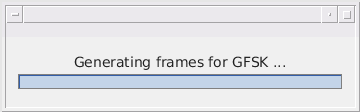

00:59:35 - Generating CPFSK frames


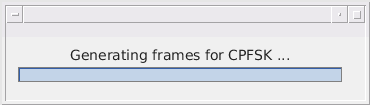

01:03:20 - Generating FM frames


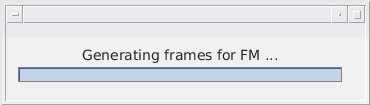

01:07:35 - Generating AM-DSB-SC frames


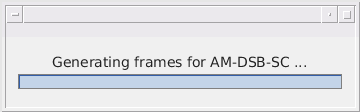

01:11:32 - Generating AM-SSB-SC frames


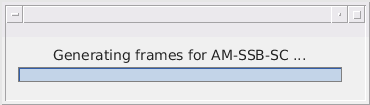

fileNameRoot = 'frame';
replace_data = true;

total_frames = numModulationTypes*numFramesPerModType * length(snr_levels);
% Check if data files exist
dataFilesExist = false;
if exist(dataDirectory,'dir')
  files_8 = dir(fullfile(dataDirectory_uint8,sprintf("%s*",fileNameRoot)));
  files_32 = dir(fullfile(dataDirectory_float32,sprintf("%s*",fileNameRoot)));
    
  if length(files_8) == total_frames && length(files_32) == total_frames && replace_data == false
    dataFilesExist = true;
  else
    rmdir(dataDirectory, 's');
  end
end

if ~dataFilesExist
  disp("Generating data and saving in data files...")
  [success,msg,msgID] = mkdir(dataDirectory_uint8);
  [success2,msg2,msgID2] = mkdir(dataDirectory_float32);

  if ~(success)
    error(msgID,msg)
  elseif ~(success2)
    error(msgID2,msg2)
  end

  for modType = 1:numModulationTypes
  
    elapsedTime = seconds(toc);
    elapsedTime.Format = 'hh:mm:ss';
    fprintf('%s - Generating %s frames\n', ...
      elapsedTime, modulationTypes(modType))
    label = modulationTypes(modType);
    dataSrc = dlhdlhelperModClassGetSource(modulationTypes(modType), sps, 2*spf, fs);
    modulator = dlhdlhelperModClassGetModulator(modulationTypes(modType), sps, fs);
    if contains(char(modulationTypes(modType)), {'FM','AM-DSB-SC','AM-SSB-SC'})
      % Analog modulation types use a center frequency of 100 MHz
      channel.CenterFrequency = 100e6;
    else
      % Digital modulation types use a center frequency of 902 MHz
      channel.CenterFrequency = 902e6;
    end
    wb = waitbar(0, sprintf("Generating frames for %s ...",label));
    for j = 1:length(snr_levels)
        waitbar(j/length(snr_levels));
        for p=1:numFramesPerModType
          % Generate random data
          x = dataSrc();
          
          % Modulate
          y = modulator(x);
          channel.SNR = snr_levels(j);
          SNR = snr_levels(j);
          % Pass through independent channels
          rxSamples = channel(y);
          
          % Remove transients from the beginning, trim to size, and normalize
          frame = dlhdlhelperModClassFrameGenerator(rxSamples, spf, spf, transDelay, sps);
          
          % Save data file
          label = char(label);
          IQ = [real(frame),imag(frame)];
    
          % Saving Int 8 Dataset
          frame_IQ = int8(IQ * 127);
          fileName = fullfile(dataDirectory_uint8, sprintf("%s%s%04d",fileNameRoot,modulationTypes(modType),p+(numFramesPerModType*(snr_levels(j)/2))));
          save(fileName, "frame_IQ", "label", "SNR")
    
          % Saving Float32 Dataset
          frame_IQ = single(IQ);
          fileName = fullfile(dataDirectory_float32, sprintf("%s%s%04d",fileNameRoot,modulationTypes(modType),p+(numFramesPerModType*(snr_levels(j)/2))));
          save(fileName, "frame_IQ", "label", "SNR")
        end
    end
  end
else
  disp("Data files exist. Skip data generation.")
end

**Create a Datastore**

To manage the files that contain the generated complex waveforms, use a `signalDatastore` object. Datastores are especially useful when each individual file fits in memory, but the entire collection does not necessarily fit.

frameDS = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);

**Generating Test Frames and Labels**

For demonstration, we extract frames for a specific modulation scheme defined by the `Target_Scheme` variable. We parse the signal datastore to collect relevant files and convert the complex baseband signals into real-valued 4-D arrays, as the deep learning network expects real inputs.

Each output frame has dimensions 1-by-`spf`-by-2-by-`N`, with the third dimension representing I/Q components: the first page holds in-phase samples, the second page holds quadrature samples. Using 1-by-`spf` convolutional filters, this format allows the network to mix I and Q data effectively, leveraging phase information.

This transformation is done using the `dlhdlhelperModClassIQAPages` function.

fileNames = frameDS.Files; % Get list of files
Target_Scheme = "8PSK";
pctExists = parallelComputingLicenseExists();
% Find indices where filename contains Target_Scheme
indices = find(contains(fileNames, Target_Scheme));
% Create subset datastore
% Creating a subset of Transformed Signal Datastore of Specified Scheme
testDS = subset(frameDS, indices);
testDSTrans = transform(testDS,@dlhdlhelperModClassIQAsPages);


Once we have transformed the mat files into pages, we import the data in the files into memory. The files have two variables: `frame` and `label`. Each [`read`](docid:matlab_ref#budsyj6-1) call to the datastore returns a cell array, where the first element is the `frame` and the second element is the `label`. To read frames and labels, use the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) functions dlhdlhelperModClassReadFrame and dlhdlhelperModClassReadLabel. Use [`readall`](docid:matlab_ref#buefs9d-1) with the `"UseParallel"` option set to `true` to enable parallel processing of the transform functions, if you have [Parallel Computing Toolbox](https://www.mathworks.com/products/parallel-computing.html) license. Because the `readall` function, by default, concatenates the output of the `read` function over the first dimension, return the frames in a cell array and manually concatenate over the fourth dimension.


% Reading Frames to be Tested on Model
testFrames = transform(testDSTrans, @dlhdlhelperModClassReadFrame);
rxTestFrames = readall(testFrames,"UseParallel",pctExists);
rxTestFrames = cat(4, rxTestFrames{:});
% Reading Labels to be Tested on Model
testLabels = transform(testDSTrans, @dlhdlhelperModClassReadLabel);
rxTestLabels = readall(testLabels, "UseParallel",pctExists);


With the test frames and labels loaded, we can feed them into the pre-training modulation classification network and observe the performance of the model on the generated data.

load dlhdltrainedModulationClassificationNetwork
trainedNet
[YPred, score] = classify(trainedNet, rxTestFrames);
% dlhdlhelperModClassPlotScores(score1,modulationTypes, title_string);